p= raw_model.predictFcn(test_data)

p = 10127×1 categorical array
     low 
     medium 
     low 
     medium 
     medium 
     low 
     medium 
     low 
     medium 
     medium 
     medium 
     low 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     low 
     medium 
     medium 
     medium 
     medium 
     medium 
     low 
     medium 


idx_low_high= find(p=='high' & y_test.demand=='low')

idx_low_high =         3641
        3721
        4256
        4260
        4292
        4294
        4357
        4383
        4492
        4874


raw_fare=x_test(idx_low_high,"avg_fare")

raw_fare = 53×1 table
    avg_fare
    ________

     10.592 
     10.547 
     9.8825 
     9.9561 
     9.8047 
     9.4138 
     10.036 
      10.95 
     13.616 
     10.014 
     10.743 
     9.6026 
     9.6268 
     9.2807 
     9.7727 
     9.7529 


summary(raw_fare)

Variables:

    avg_fare: 53×1 double

        Values:

            Min        8.2469 
            Median     10.077 
            Max          13.8 



mean(raw_fare.avg_fare)

ans = 10.4707

p= final_model.predictFcn(test_data)

p = 10127×1 categorical array
     low 
     low 
     low 
     low 
     low 
     low 
     medium 
     low 
     medium 
     medium 
     medium 
     low 
     low 
     medium 
     medium 
     medium 
     low 
     medium 
     medium 
     low 
     medium 
     medium 
     low 
     medium 
     medium 
     low 
     medium 
     medium 
     low 
     low 


idx_low_high= find(p=='high' & y_test.demand=='low')

idx_low_high =         3421
        3641
        3721
        3748
        3886
        4191
        4260
        4294
        4357
        4652


raw_fare=x_test(idx_low_high,"avg_fare")

raw_fare = 91×1 table
    avg_fare
    ________

     12.252 
     10.592 
     10.547 
      10.41 
      10.71 
      10.12 
     9.9561 
     9.4138 
     10.036 
     10.425 
     7.5893 
     9.3087 
     9.4509 
     8.2971 
     9.4185 
     8.8479 


summary(raw_fare)

Variables:

    avg_fare: 91×1 double

        Values:

            Min        7.5893 
            Median     10.013 
            Max          13.8 



mean(raw_fare.avg_fare)

ans = 10.1399

p= raw_model.predictFcn(test_data)

p = 10127×1 categorical array
     low 
     medium 
     low 
     medium 
     medium 
     low 
     medium 
     low 
     medium 
     medium 
     medium 
     low 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     medium 
     low 
     medium 
     medium 
     medium 
     medium 
     medium 
     low 
     medium 


idx_low_high= find(p=='medium' & y_test.demand=='low')

idx_low_high =      4
     5
    14
    21
    30
    31
    32
    33
    59
    63


raw_fare=x_test(idx_low_high,"avg_fare")

raw_fare = 1241×1 table
    avg_fare
    ________

         26 
         52 
     49.625 
     49.333 
         26 
     49.875 
         52 
         26 
         52 
         52 
     49.688 
       52.5 
      50.45 
      47.76 
         52 
      43.25 


summary(raw_fare)

Variables:

    avg_fare: 1241×1 double

        Values:

            Min          2.75 
            Median     11.682 
            Max        53.438 



mean(raw_fare.avg_fare)

ans = 22.0907

p= final_model.predictFcn(test_data)

p = 10127×1 categorical array
     low 
     low 
     low 
     low 
     low 
     low 
     medium 
     low 
     medium 
     medium 
     medium 
     low 
     low 
     medium 
     medium 
     medium 
     low 
     medium 
     medium 
     low 
     medium 
     medium 
     low 
     medium 
     medium 
     low 
     medium 
     medium 
     low 
     low 


idx_low_high= find(p=='medium' & y_test.demand=='low')

idx_low_high =     14
    21
    31
    32
    59
    63
    68
    86
    93
   123


raw_fare=x_test(idx_low_high,"avg_fare")

raw_fare = 232×1 table
    avg_fare
    ________

     49.625 
     49.333 
     49.875 
         52 
         52 
         52 
     49.688 
      47.76 
         52 
      50.25 
         52 
         52 
     46.489 
         52 
         52 
     51.688 


summary(raw_fare)

Variables:

    avg_fare: 232×1 double

        Values:

            Min        7.1429 
            Median     28.997 
            Max        53.438 



mean(raw_fare.avg_fare)

ans = 27.8890

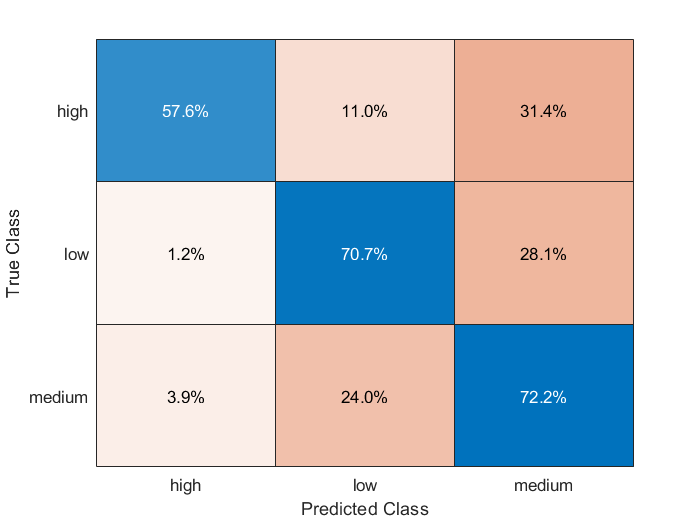

confusionchart(y_test.demand,p,"Normalization","row-normalized")